Jireh Diboto-Mofa

Lab10 // BMEN 1400

data = readmatrix('flow.csv') ;
time = data(:,1) ;
flow = data(:,2) ;

smoothflow = smooth(flow) ;

'smooth' command smooths data

Peaks = [] ;
Pktimes = [] ;
Pkidx = [] ;

for i = 2:length(time) ;
    if smoothflow(i) > smoothflow(i-1) && smoothflow(i) > smoothflow(i+1) && smoothflow(i) > 300 
            Peaks(end+1) = smoothflow(i) ;
            Pktimes(end+1) = time(i) ;
            Pkidx(end+1) = i ;
    end
end


Troughs = [] ;
Trtime = [] ;
Tridx = [] ;


for t = 1:length(Peaks)
   for k = Pkidx(t):-1:2 ;
        if smoothflow(k) < smoothflow(k-1) && smoothflow(k) < smoothflow(k+1) ;
             Troughs(end+1) = smoothflow(k) ;
             Trtime(end+1) = time(k) ; 
             Tridx(end+1) = k ;
            break
         end
    end
end

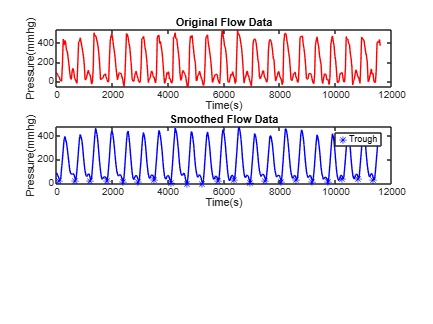

figure(1) ;
subplot(3,1,1) ;
plot(time,flow,"-r") ;
title('Original Flow Data')
xlabel('Time(s)')
ylabel('Pressure(mmhg)')


subplot(3,1,2) ;
plot(Trtime, Troughs,"*b",time,smoothflow,"-b" ) 
title('Smoothed Flow Data')
xlabel('Time(s)')
ylabel('Pressure(mmhg)')
legend("Trough")

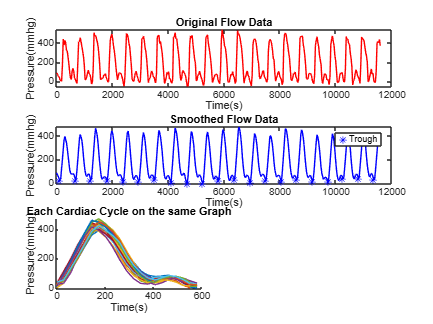

area = [] ;
subplot(3,2,5)
hold on

    for seg = 1:length(Troughs)
        try
            segflow = smoothflow(Tridx(seg):Tridx(seg+1)) ;
            %from the first trough to the second trough
        catch
            break
        end
        
        segtime = time(Tridx(seg):Tridx(seg+1)) ;
        t = segtime - segtime(1) ;
        plot(t,segflow) ; 
        area(end+1) = trapz(t,segflow) ;
        
    end

title('Each Cardiac Cycle on the same Graph')
xlabel('Time(s)')
ylabel('Pressure(mmhg)')
    
hold off

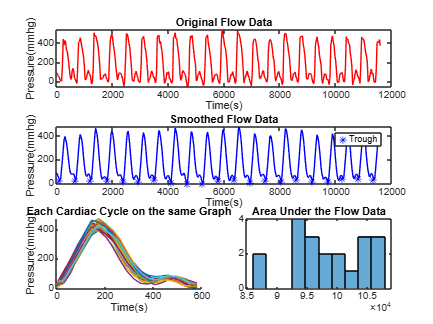

subplot(3,2,6)
histogram(area,10)
title('Area Under the Flow Data')



mean_area = mean(area) ;
std_areas = std(area) ;

fprintf('The mean is %d and the std is %d' ,round(mean_area,2),round(std_areas,2))

The mean is 9.850970e+04 and the std is 6.313130e+03

%d to indicate double.